# **Lab 1:  Random variables and estimation theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076), Franz Lampel (Flux 7.064)

Assistants: Yizhou Huang, Ben Luijten, Agata Barbagini, Xueting Li

**Students (Name + IDs): Austin Ivantsiv 1372742, Can Bozdoğan 1668463, Edgar Luhulima 148420, Idan Grady 1912976**

**Group #: 14**

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 4 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, running the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by emailing the lab assistants. The email address are available on Canvas.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure the all the text is readable. Below some useful commandsfor these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

***Please submit this lab on Canvas by 10/10/22 at 23:59.***

## Introduction

In this lab, we are going to prove the frequentist definition of probability and investigate sampling of random variables and the central-limit theorem in MATLAB. We are also going to implement maximum-likelihood estimator for noisy ultrasound signals.

## **Assignment 1 - Probability and frequency**

In the first assignment, we are going to explore a traditional probability problem: rolling a dice. 

The *classic* definition of probability states that if a random experiment can result in $N$ mutually exclusive and equally likely outcomes, and if an event $A\;$results from the occurrence of $N_A$ outcomes, then the probability $A$ is defined as


$$Pr[A] =  \frac{N_A}{N}. ~~~~~~~(1)$$
 

The *frequentist* definition of probability, also known as *relative probability*, calculates probability based on how often an event occurs. The relative frequency of an event is given by


$$f_A =\frac{\textrm{number}\;\textrm{of}\;\textrm{occurrences}\;\textrm{of}\;\textrm{event}\;A}{\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{observations}}=\frac{N\left(A\right)}{A}\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


where $N\left(\cdot \right)$ denotes the number of occurrences of a certain event and $N$ the total number of observations. The relative frequency can be understood as how often event $A$ occurs relative to all observations. 

**QUESTION 1a**

If you have a dice which has six faces numbering from 1 to 6. You roll the dice for six rounds. 

What is the probability of getting a 1 during all rounds? 

What is the probability of getting all 1s? 

What is the probability of only getting 1s at the third and the fourth rounds whereas the other numbers at other rounds (like XX11XX)? 

Write down your problem-solving process. 

**ANSWER**: (write solution here. You can insert equations by going to 'Insert', and then 'Equations')


$$\Pr \left\lbrack \textrm{at}\;\textrm{least}\;\textrm{one}\;1\right\rbrack =1-\frac{5^6 }{6^6 }=\frac{31031}{46656}$$


The probability of getting all 1s is the product of the probability of getting 1 in a round for all rounds.


$$\Pr \left\lbrack \textrm{all}\;1s\right\rbrack =\frac{1^6 }{6^6 }=\frac{1}{46656}$$


The probability of getting 1s at the 3rd and 4th rounds whereas the other numbers at other rounds is the product of the probability of getting 1 at 3rd and 4th rounds and the probability of getting other numbers at other rounds.


$$\Pr \left\lbrack 1\;\textrm{at}\;3\textrm{rd}\;\textrm{and}\;4\textrm{th}\;\textrm{round}\right\rbrack =\frac{\left(5^4 \times 1^2 \right)}{6^6 }=\frac{625}{46656}$$


**QUESTION 1b**

Now, you are going to implement a MATLAB script to prove that the results you obtained from question **1a** are correct. 

Let's take 'What is the probability of getting all 1s? ' as an example. 

Please write a script to repeat the experiment for 10000, 50000 and 100000 times and calculate the relative frequency of getting all 1s if you roll the dice six times. Compare the results obtained by 10000, 50000 and 100000 times with your theoretical result in question **1a**, do you get the same result? If not, why?

HINT:  A useful command to simulate this experiment is `random. `(optional) To avoid having a different result every time you run the algorithm, you may fix the random seed using the function `rng. `

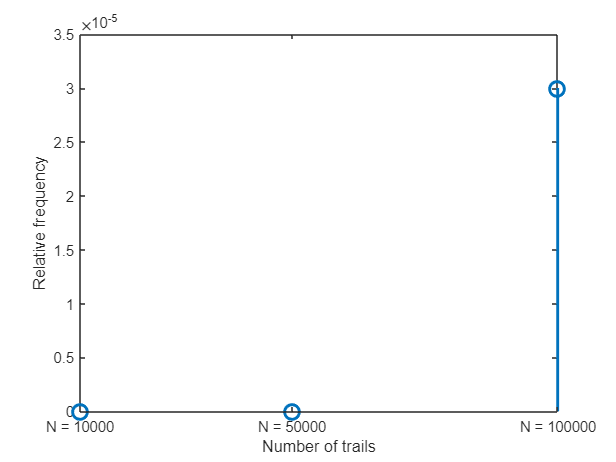

% Code
% You can use 'rng' to fix the random seed, so that if you re-run the code,
% it will provide you with the same set of random variables.
N = [10000 50000 100000]; % number of trials
rng('default');

A = [1 1 1 1 1 1]; % array of all 1's 

sum1b = [0 0 0]; % summation array for each N

% Experiment with first number of trial
res = randi(6,N(1),6);
for i = 1:N(1)
    if ismember(A,res(i,:),"rows")
        sum1b(1)=sum1b(1)+1;
    end
end
% Experiment with second number of trial
res = randi(6,N(2),6);
for i = 1:N(2)
    if ismember(A,res(i,:),"rows")    
        sum1b(2)=sum1b(2)+1;
    end
end
% Experiment with third number of trial
res = randi(6,N(3),6);
for i = 1:N(3)
    if ismember(A,res(i,:),"rows") 
        sum1b(3)=sum1b(3)+1;
    end
end

freq = [sum1b(1)/N(1) sum1b(2)/N(2) sum1b(3)/N(3)]; % Compute relative frequency

% Plot (Y-axis: Relative frequency; X-aixs: Number of trails)
% Use 'xticks', 'xticklabels' to change the labels of your x-axis.
stem(N,freq,'MarkerSize',10,'LineWidth',2);
xlabel('Number of trails');
ylabel('Relative frequency');
xticks(N);
xticklabels(["N = 10000","N = 50000","N = 100000"]);

**ANSWER:**

In terms of classic definition of probability, the probability of getting all 1s in all 6 rounds is $\frac{1}{46656}=2\ldotp 143{\textrm{x10}}^{-5}$ while the experiment (frequentistic definition of probability) with$N=100000$ gives a relative frequency of $3{\textrm{x10}}^{-5} \ldotp$ This difference can be explained by under the assumptions of classical definition of probability and the frequentist definition of probability. Former definition states that in absance of elevant evidence all posible outcomes are equally likely (principle of indifference). Latter definition approaches the problem differently since the probability calculation is based on how the event is occur in the number of obervations. In a sense, the frequency of event (getting 1's in all 6 rounds in our case) relative to all observations is defined as the relative frequency which is the relative probability. 

                                                               

Because of that definition, the true probability can only be determined theoretically by an infinitely large number of observations. 

                                                                                

Therefore, low number of total observations such as $N=1000$ and $N=50000$ does not give accurate estimate of the true underlying probability of an event occuring while $N=100000$ with $3{\textrm{x10}}^{-5}$ close to the classic definition of probability result.

## Assignment 2 - Moments of a random variable

In the following experiment, we construct a random variable $X_N \left\lbrack n\right\rbrack \;$as the sum of $N$ RVs $x_i$ as follows:

$X_N =\frac{1}{N}\sum_{i=1}^N x_i \left\lbrack n\right\rbrack$     with $N=1,\;2,\;\ldotp \ldotp \ldotp$                         (3)

The random processes $x_i \left\lbrack n\right\rbrack$, for $i=1,2,\ldotp \ldotp \ldotp ,N$, are $N$ IID stationary Gaussian random processes with mean $E\left\lbrace x_i \left\lbrack n\right\rbrack \right\rbrace =\mu_i =\mu$ and variance $E\left\lbrace x_i^2 \left\lbrack n\right\rbrack \right\rbrace =\sigma_i^2 =\sigma^2$.

**QUESTION 2a**

Calculate an analytical expression for the mean $\mu_{X_N } =E\left\lbrace X_N \right\rbrace$and the variance $\sigma_{X_N }^2 =E\left\lbrace X_N^2 \right\rbrace -E{\left\lbrace X_N \right\rbrace }^2$ of the sum RV $X_N$ as a function of $N\ldotp$ 

HINT: The $x_i$ are IID (independent, identically distributed)

**ANSWER**: Please insert the analytical expression here.

We want to proof $E\left\lbrack X_N \right\rbrack =\;\mu \;$and, we know that $X_N =\frac{1}{N}\sum_{i=1}^N x_i \left\lbrack n\right\rbrack$for $i=1,2,\ldotp \ldotp \ldotp ,N$, 


$$\begin{array}{l}
\\
E\left\lbrack \frac{1}{N}\cdot \sum_{i=1}^N x_i \left\lbrack n\right\rbrack \right\rbrack =\mu 
\end{array}$$
 

Since $\frac{1}{N}$ is not dependent on the expectation, we can take that term out of expectation operator.


$$E\left\lbrack \frac{1}{N}\cdot \sum_{i=1}^N x_i \left\lbrack n\right\rbrack \right\rbrack =\frac{1}{N}\cdot E\left\lbrack \sum_{i=1}^N x_i \left\lbrack n\right\rbrack \right\rbrack$$


We know that we can apply linear transformation on expected value (linearly seperable)


$$\frac{1}{N}\cdot E\left\lbrack x_1 \left\lbrack n\right\rbrack +x_2 \left\lbrack n\right\rbrack +x_3 \left\lbrack n\right\rbrack \cdots +x_N \left\lbrack n\right\rbrack \right\rbrack$$
 


$$\frac{1}{N}\left(E\left\lbrack x_1 \left\lbrack n\right\rbrack \right\rbrack +E\left\lbrack x_2 \left\lbrack n\right\rbrack \right\rbrack +E\left\lbrack x_3 \left\lbrack n\right\rbrack \right\rbrack +\cdots +E\left\lbrack x_N \left\lbrack n\right\rbrack \right\rbrack \right)$$


We know that $x_i \left\lbrack n\right\rbrack$identically distributed and independent from each other, which means they have the same mean. Hence,


$$\frac{1}{N}\cdot N\cdot \mu \;=\mu$$
  

Variance is the second order moment.


$$\begin{array}{l}
\textrm{Var}\left\lbrack X_N \right\rbrack =\textrm{Var}\left\lbrack \frac{1}{N}\sum_{i=1}^N x_i \left\lbrack n\right\rbrack \right\rbrack \\
\textrm{Var}\left\lbrack X_N \right\rbrack =\textrm{Var}\left\lbrack \frac{1}{N}x_1 \left\lbrack n\right\rbrack +\frac{1}{N}x_2 \left\lbrack n\right\rbrack +\frac{1}{N}x_3 \left\lbrack n\right\rbrack +\cdots \frac{1}{N}x_N \left\lbrack n\right\rbrack \right\rbrack 
\end{array}$$
 

We know that $\textrm{Var}\left\lbrack X\right\rbrack =E\left\lbrack X^2 \right\rbrack -\mu$ and linear combination of variances $x_i \left\lbrack n\right\rbrack$ equals to variance of $X_N$. (IID) Therefore,


$$\begin{array}{l}
\textrm{Var}\left\lbrack X_N \right\rbrack =\frac{1}{N^2 }\textrm{Var}\left\lbrack x_1 \left\lbrack n\right\rbrack \right\rbrack +\frac{1}{N^2 }\textrm{Var}\left\lbrack x_2 \left\lbrack n\right\rbrack \right\rbrack +\frac{1}{N^2 }\textrm{Var}\left\lbrack x_3 \left\lbrack n\right\rbrack \right\rbrack +\cdots \frac{1}{N^2 }\textrm{Var}\left\lbrack x_N \left\lbrack n\right\rbrack \right\rbrack \\
\textrm{Var}\left\lbrack X_N \right\rbrack =\frac{1}{N^2 }\left\lbrack \sigma^2 +\sigma^2 +\sigma^2 +\cdots \sigma^2 \right\rbrack \\
\textrm{Var}\left\lbrack X_N \right\rbrack =\frac{1}{N^2 }\cdot N\cdot \sigma^2 \\
\textrm{Var}\left\lbrack X_N \right\rbrack =\frac{\sigma^2 }{N}
\end{array}$$
  

**QUESTION 2b**

Calculate an analytical expression for the expectation of $E\left\lbrace X_N^3 \right\rbrace$,  the 3rd moment of $X_N$, ${M_X }^3$, and the skewness of the random process. 

**ANSWER**: Please insert the analytical expression here.


$$\begin{array}{l}
\textrm{we}\;\textrm{would}\;\textrm{solve}\;\textrm{it}\;\textrm{in}\;\textrm{matrix}\;\textrm{form}\\
E\left\lbrack \frac{{\left(X-u\right)}^3 }{\sigma^3 }\right\rbrack =\left(\frac{E\left\lbrack X^3 \right\rbrack -3uE\left\lbrack X^2 \right\rbrack +3u^3 E\left\lbrack X\right\rbrack -u^3 }{\sigma^3 }\right)\\
\textrm{because}\;\textrm{we}\;\textrm{know}\;\textrm{it}\;\textrm{follows}\;a\;\textrm{normal}\;\textrm{distribution},\textrm{we}\;\textrm{can}\;\textrm{equate}\;\textrm{it}\;\textrm{to}\;0\\
=\left(\frac{E\left\lbrack X^3 \right\rbrack -3u\left(E\left\lbrack X^2 \right\rbrack -\textrm{uE}\left\lbrack X\right\rbrack \right)-u^3 }{\sigma^3 }\right)=0\\
\left(\frac{E\left\lbrack X^3 \right\rbrack -3u\left(E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 \right)-u^3 }{\sigma^3 }\right)=0\\
\textrm{By}\;\textrm{definition}\;E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 =\sigma^2 \\
\left(\frac{E\left\lbrack X^3 \right\rbrack -3u\sigma^2 -u^3 }{\sigma^3 }\right)=0\\
\left(\frac{E\left\lbrack X^3 \right\rbrack }{\sigma^3 }\right)=\left(\frac{3u\sigma^2 +u^3 }{\sigma^3 }\right)\\
\textrm{Hence},\\
E\left\lbrack X^3 \right\rbrack =3u\sigma^2 +u^3 
\end{array}$$


**QUESTION 2c**

Implement a Monte-Carlo simulation in MATLAB to generate RVs $x_i$, for $i=1,2,\ldotp \ldotp \ldotp ,5$, with a gaussian distribution. For each of these RVs, generate 1000 IID samples ($n=1000$) with parameters of the exponential distribution with $\mu =5$ and $\sigma =2$. Construct $X_{\textrm{gN}}$ for $N=1,\;2,\;\textrm{and}\;5$ and make a *subplot* of $X_{\textrm{g1}}$, $X_{\textrm{g2}}$ and $X_{\textrm{g5}}$. Calculate mean, variance and skewness of $X_{\textrm{g5}}$.

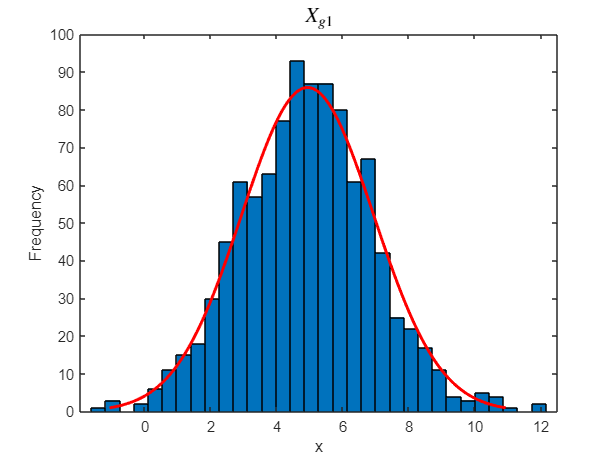

% Code
clc
% You can use 'rng' to fix the random seed, so that if you re-run the code,
% it will provide you with the same set of random variables.
% Learn how to generate random gaussian variables with MATLAB function
clear all;
n = 1000; % number of trials
rng('default');

% Generate RVs
miu = 5;
sigma = 2;
x1 = normrnd(miu,sigma,[n,1]);
x2 = normrnd(miu,sigma,[n,1]);
x3 = normrnd(miu,sigma,[n,1]);
x4 = normrnd(miu,sigma,[n,1]);
x5 = normrnd(miu,sigma,[n,1]);

% Construct XgN
Xg1 = x1;
Xg2 = (1/2)*(x1+x2);
Xg5 = (1/5)*(x1+x2+x3+x4+x5);


% Plot 
% Use the 'subplot' function to generate a set of subplots within the figure
% Don't forget to add labels and titles
%subplot(3,1,1);
histfit(Xg1);
title('$X_{g1}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');

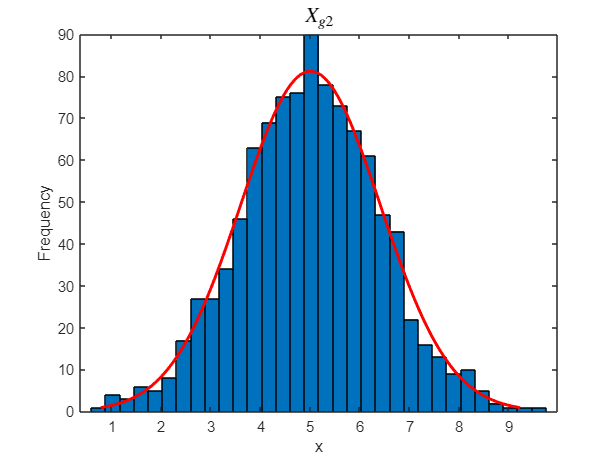


%subplot(3,1,2);
histfit(Xg2);
title('$X_{g2}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');

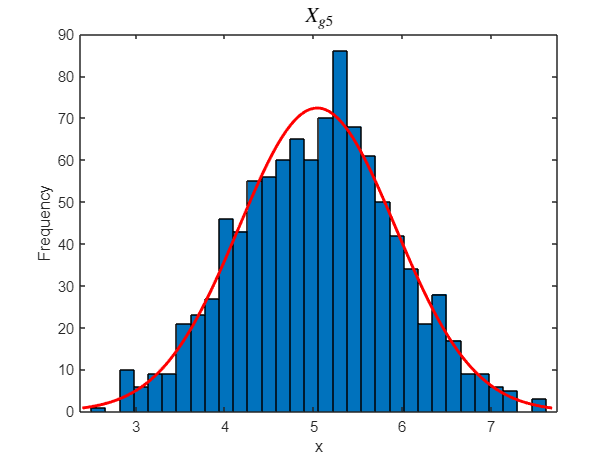


%subplot(3,1,3);
histfit(Xg5);
title('$X_{g5}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');



fprintf('Mean of Xg5: %.4f\n',mean(Xg5));

Mean of Xg5: 5.0402


fprintf('Variance of Xg5: %.4f\n',var(Xg5));

Variance of Xg5: 0.7775


fprintf('Skewness of Xg5: %.4f\n',skewness(Xg5));

Skewness of Xg5: 0.0047


**QUESTION 2d**

Compare the results obtained from question **2a **and **2b** with your implementation in question **2c**. Are they the same? If not, why? Can you make a general statement on the sum of multiple independent Gaussian distributed random processes? (for instance which distribution it follows)

**ANSWER:**

**Yes, they are the same. **

**It is also predictable as the sum of independent Gaussian random processes follows a Gaussian distribution.**

In probability theory, the **central limit theorem** (**CLT**) establishes that, in many situations, when independent random variables are summed up, their **normalized sum** tends toward a normal distribution even if the original variables themselves are not normally distributed.

**QUESTION 2e**

Please write down the analytical expression of the normalized sum of $N$ random processes$\;x_i \left\lbrack n\right\rbrack$, $Z_N$, as a function of mean $\mu_{\textrm{XN}}$ standard deviation $\sigma_{\textrm{XN}}$.

**ANSWER: **Please insert the analytical expression here.

A normlise distribution has zero mean and unit variance. To achieve this, the distribution is linearly shifted and stretched so that it becomes normlized.

By definition of CLT:


$${Z_n }_{\;} =\frac{\bar{X_n } -\mu \;\;}{\sqrt{\frac{{\sigma_i }^2 }{n}}}\;\;,\textrm{when}\;n\;\textrm{appraoches}\;\textrm{infinity},\textrm{the}\;\textrm{distibution}\;\textrm{of}\;\textrm{the}\;\textrm{sample}\;\textrm{mean}\;\textrm{appraoches}\;\textrm{normality}\ldotp$$
 

where $\sqrt{\frac{{\sigma_i }^2 }{n}}$ is called the standard error. 

We know that $\bar{X_n } =\frac{1}{N}\sum_{i=1}^N \left(x_i \left\lbrack n\right\rbrack \right)$, and ${Z_n }_{\;}$ can be also written as $\frac{X_1 +X_2 +\ldotp \ldotp \ldotp X_n -\left(n\mu \right)}{\sqrt{n}\sigma_i }$ 

Hence, if we normlize for N processes,


$$\begin{array}{l}
Z_N =\frac{\frac{1}{N}\sum_{i=1}^N \left(x_i -E\left\lbrack \bar{X_N } \right\rbrack \right)\;\;\;}{\frac{\sigma_i }{\sqrt{N}}}=\frac{\sqrt{N}\frac{1}{N}\sum_{i=1}^N \left(x_i -E\left\lbrack \bar{X_N } \right\rbrack \right)\;\;\;}{\sigma_i }=\frac{\sum_{i=1}^N \left(x_i -E\left\lbrack \bar{X_N } \right\rbrack \right)\;\;\;}{\sigma_{i\;} \sqrt{N}}\\
=\frac{\sum_{i=1}^N \left(x_i -\mu_{\textrm{XN}} \right)\;\;\;}{\sigma_i \sqrt{N}}\;=\frac{X_N -\mu_{\textrm{XN}} }{\sigma_{\textrm{XN}} }\\
\textrm{Where}\;\sigma_{\textrm{XN}} =\frac{\sigma_i }{\sqrt{N}}
\end{array}$$


**QUESTION 2f**

Repeat the implementation in question **2c**, but this time replace the gaussian distribution with a binomial distribution with $n=6$ and $p=0\ldotp 2$. Try $N=5\;,10\;\textrm{and}\;30$, and plot the histograms of $Z_5$, $Z_{10}$, $Z_{30}$. Does your implementation converge to Gaussian distribution when $N$ is 'sufficiently' large? Please comment on this. 

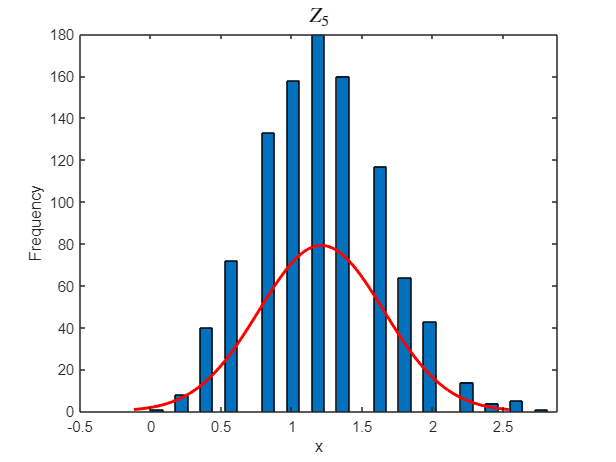

% Code
clc
% You can use 'rng' to fix the random seed, so that if you re-run the code,
% it will provide you with the same set of random variables.
clear all;
rng('default');

% Generate RVs
n = 6;
p = 0.2;

% Construct ZN
size = 1000;

Z5 = 0;
for i = 1:5
    Z5 = binornd(n,p,size,1)+Z5;
end
Z5 = Z5*(1/5);

Z10 = 0;
for i = 1:10
    Z10 = binornd(n,p,size,1)+Z10;
end
Z10 = Z10*(1/10);

Z30 = 0;
for i = 1:30
    Z30 = binornd(n,p,size,1)+Z30;
end
Z30 = Z30*(1/30);

% Plot 
% Use the 'subplot' function to generate a set of subplots within the figure
% Don't forget to add labels and titles
%subplot(3,1,1);
histfit(Z5);
title('$Z_{5}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');

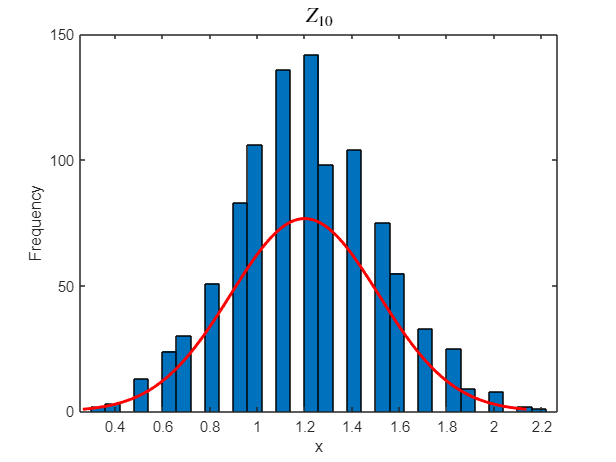


%subplot(3,1,2);
histfit(Z10);
title('$Z_{10}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');

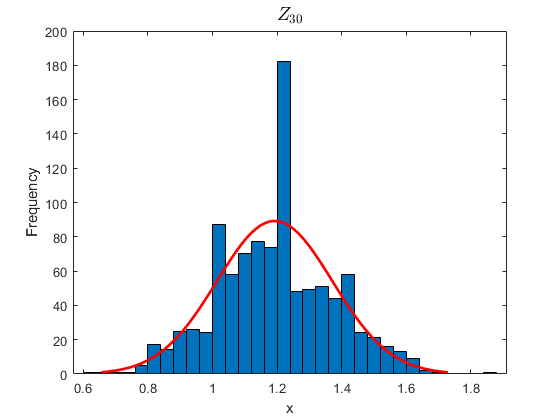


%subplot(3,1,3);
histfit(Z30);
title('$Z_{30}$','Interpreter','latex','FontSize', 14);
xlabel('x');
ylabel('Frequency');

pause(1)

**ANSWER:**

**Yes, when N is sufficiently large, implementation turned to be a Gaussian distribution. It is regardless of it's orginal (population) distribution.**

## Assignment 3 - Auto-correlation and Cross-correlation

In this section, we will filter an input signal, which is a discrete random process, to generate an output signal, which is a new discrete random process. We will study the statistical properties of the output process and its relation with the input process and the filtering operation. The figure below is a system in which the input signal $x\left\lbrack n\right\rbrack$ is a white Gaussian random process with zero mean and unit variance. This input signal $x\left\lbrack n\right\rbrack$ is used as the input to a Low Pass Filter (LPF), from which the impulse response is denoted by $h\left\lbrack n\right\rbrack$ and the frequency response by $H\left(e^{j\theta } \right)$.

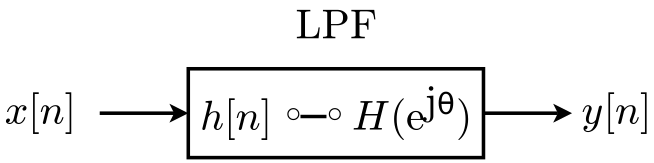

In the first instance we are using the very simple LPF:


$$h\left\lbrack n\right\rbrack =\frac{1}{2\;}\left(\delta \left\lbrack n\right\rbrack +\delta \left\lbrack n-1\right\rbrack \right)$$


Thus, in this case, the output random process y[n] can be described by the following difference equation:


$$y\left\lbrack n\right\rbrack =\frac{1}{2\;}\left(x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack \right)$$


which implies that the output samples are averaged values of 2 succeeding input samples.

a) Derive by hand the autocorrelation$r_y \left\lbrack l\right\rbrack =E\left\lbrace y\left\lbrack n\right\rbrack y\left\lbrack n-l\right\rbrack \right\rbrace$ of the random process $y\left\lbrack n\right\rbrack$.

**ANSWER:**


$$\begin{array}{l}
r_x \left\lbrack l\right\rbrack =\sigma^2 \delta \left\lbrack l\right\rbrack \\
r_{\textrm{yx}} \left\lbrack l\right\rbrack =r_x \left\lbrack l\right\rbrack \ast h\left\lbrack l\right\rbrack =\left(\sigma^2 \delta \left\lbrack l\right\rbrack \right)*\left(\frac{1}{2}\left(\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)\right)=\frac{\delta^2 }{2}\left(\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)\\
r_y \left\lbrack l\right\rbrack =r_{\textrm{yx}} \left\lbrack l\right\rbrack \ast h\left\lbrack -l\right\rbrack =\frac{\delta^2 }{2}\left(\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)*\frac{1}{2}\left(\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)=\frac{\sigma^2 }{4}\left(\delta \left\lbrack l+1\right\rbrack +2\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\sigma }^2 =1\Rightarrow \;=\frac{1}{4}\left(\delta \left\lbrack l+1\right\rbrack +2\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)
\end{array}$$


b) Derive by hand the PSD $P_y \left(e^{j\theta } \right)$ of the random process $y\left\lbrack n\right\rbrack$ in two different ways, namely first as the FTD of $r_y \left\lbrack l\right\rbrack$ and second as $P_y \left(e^{j\theta } \right)=P_x \left(e^{j\theta } \right)\cdot \left|H\left(e^{j\theta } \right){\left|\right.}^2 \right.$.

**ANSWER:**

**Method 1:**


$$\begin{array}{l}
\textrm{Fourier}\;\textrm{of}\;r_y \left\lbrack l\right\rbrack =\frac{1}{4}\left(\delta \left\lbrack l+1\right\rbrack +2\delta \left\lbrack l\right\rbrack +\delta \left\lbrack l-1\right\rbrack \right)\Rightarrow P_y \left(e^{j\theta } \right)=\sum_{l\;=-\infty \;}^{\infty \;} r_y \left\lbrack l\right\rbrack \cdot e^{-\textrm{jl}\theta \;} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{1}{4}\left(e^{j\theta } +2+e^{-j\theta } \right)
\end{array}$$


**Method 2:**


$$\begin{array}{l}
P_y \left(e^{j\theta } \right)=P_x \left(e^{j\theta } \right)\cdot \left|H\left(e^{j\theta } \right){\left|\right.}^2 \right.\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=P_x \left(e^{j\theta } \right)\cdot \left(H\left(e^{j\theta \;} \right)\cdot H^* \left(e^{j\theta } \right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=P_x \left(e^{j\theta } \right)\cdot \left(\frac{1}{2}\left(1+e^{-j\theta } \right)\cdot \frac{1}{2}\left(1+e^{j\theta } \right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=P_x \left(e^{j\theta } \right)\cdot \frac{1}{4}\left(e^{j\theta } +2+e^{-j\theta } \right)\\
P_x \left(e^{j\theta } \right)=\sigma^2 =1\Rightarrow =\frac{1}{4}\left(e^{j\theta } +2+e^{-j\theta } \right)
\end{array}$$


# **Part 2 - Estimation Theory**

Ultrasound imaging is based on the pulse-echo principle. First, a pressure pulse is transmitted towards a region of interest by the ultrasound transducer consisting of multiple transducer elements (sensors). Within the medium $X$, scattering occurs due to

 inhomogeneities in density, speed-of-sound and other non-linear behavior. The resulting 

back-scattered echoes are recorded using the same transducer elements, yielding a set of radio-frequency (RF) signals $Y$ with added noise $\mathit{\mathbf{N}}$. 

This can be described by the linear model

$Y=\;A\;X+N$        (4)

where $A$ is a measurement matrix that models the wave propagation (i.e. the travel time) and array response. 

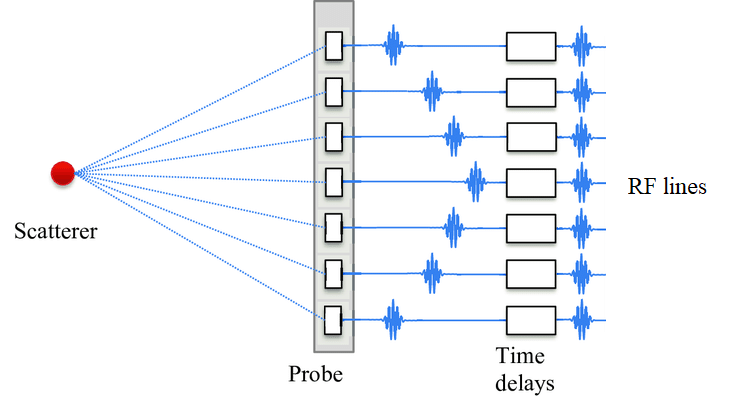

In order to create an image, we need to focus the received signals to each image pixel. This is done by applying delays to the received signal based on their respective travel time. This process is also known as time-of-flight correction. After time-of-flight correction our model can be written in vector form for each pixel independently such that.

$\mathit{\mathbf{y}}={\mathit{\mathbf{a}}}_{{\;}_{\theta \;} } \;x+\mathit{\mathbf{n}}$        (5)

where $\mathit{\mathbf{y}}\in \Re^m ,x\in \Re^1 \;$ and $n\in \Re^m$ denote the delayed RF signals, the scattering intensity, and additive noise, respectively, for *m* elements . The array response is denoted by ${\mathit{\mathbf{a}}}_{{\;}_{\theta \;} } \in \Re^m$.

In order to reconstruct an interpretable image from our measurements, we need to find the scattering intensity. It is however not possible to find the exact value of *x, *due to noise. In this assignment we will implement a maximum likelihood estimator for reconstructing an ultrasound image from a set of noisy measurement.

### Assignment 4 - Data processing and time-of-flight correction.

**QUESTION 4a**

Load the ultrasound data in **rf_data.mat** from a set of point-scatterers. The data comprises 64 elements, with each 2048 time samples, stored in the format (time samples, elements), Plot the RF signal of the 32th (center) element over time. 

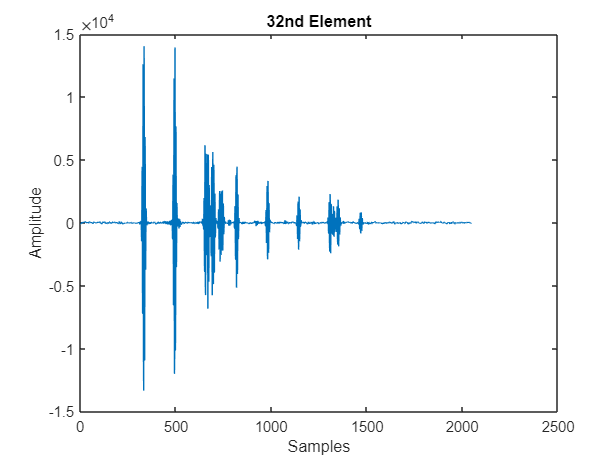

% Load and plot the data (~3 lines of code)
clc
clear

close all
load rf_data.mat; % load data
plot(Y(:,32)); % plotting


ylabel("Amplitude");
xlabel("Samples");
title("32nd Element");

**QUESTION 4b**

The plot from **4a** is also called an A-mode (amplitude) image. Often, it is more informative to reconstruct a so called B-mode (brightness) image, which provides a 2D scattering map of the imaging region. Lets first take the envelope of the received signal. An easy way of finding the envelope of a modulated signal (without knowing the carrier frequency) is by taking the absolute value of the Hilbert transform `hilbert(). `

Visualize the resulting envelope image.

**HINT:** Use imagesc() for plotting

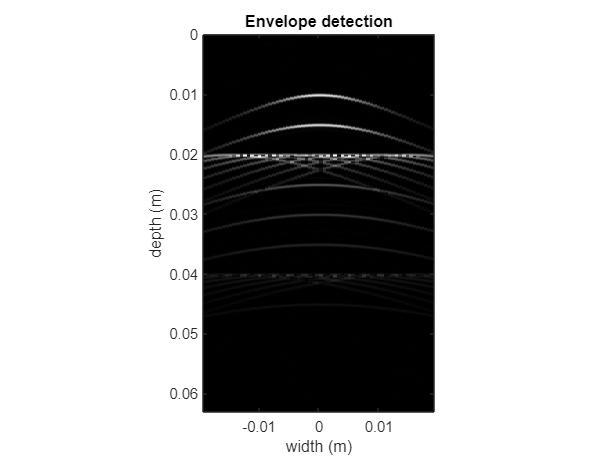

% Generate axis from our imaging region
sz = size(Y);

x_axis = linspace(-19e-3,19e-3, sz(2)); % -19mm to 19mm wide
z_axis = linspace(0,63e-3, sz(1)); % 0mm to 63mm in depth

% Envelope detection (~2 lines of code)
env = hilbert(Y([1:end],[1:end])); %perform Hilbert

% Visualization (~2 lines of code)
imagesc(x_axis,z_axis,abs(env));
title('Envelope detection');
xlabel('width (m)');
ylabel('depth (m)');
colormap gray; axis image;

**QUESTION 4c**

Since ultrasound signals have a high dynamic range, the data is typically logarithmically compressed (i.e. converted to dB scale) to yield an interpretable image. 

Repeat the steps from **4b**, but now normalize the envelope data such that it ranges between [0,1], and convert it to decibels. Plot the resulting image with a dynamic range of 60dB, what differences do you see?

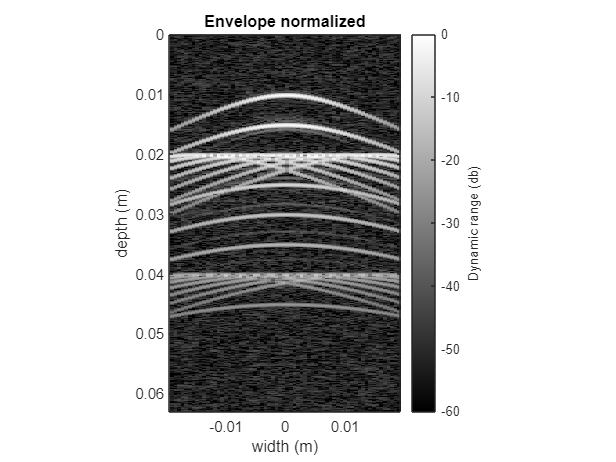

% Envelope detection (~2 lines of code)
env = hilbert(Y([1:end],[1:end])); % perform Hilbert
env_abs = abs(env/max(max(env))); % compute absolute value
env_db = mag2db(env_abs); % convert to dB

% Visualization (~2 lines of code)
imagesc(x_axis,z_axis,env_db);
caxis([-60, 0]);
title('Envelope normalized');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**ANSWER:**

**After normalization and conversion to dB, the data on the lower magnitude range of the spectrum are more visible. The areas of the image that previously showed only black now have more details.**

**QUESTION 4d**

So far we have visualized the raw unfocussed RF signals. We are now going to focus the signals using time-of-flight correction. Use the provided `tof_correction()` function to align the RF signals to each pixel. The resulting matrix has the shape `(x, z, elements). I`n other words, for each pixel in our grid, we get 64 individual signal contributions.

Apply time of flight correction and plot the images corresponding to the 1st, 32th and 64th element, what do you see?

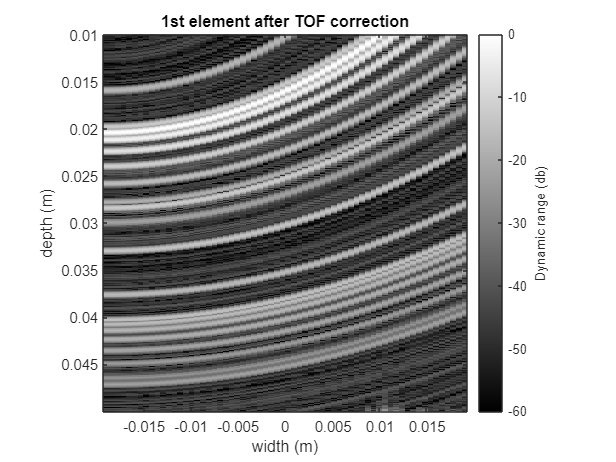

% TOF grid definition
% A sub-region is choosen to speed up calculations
z_axis = z_axis(325:1625); % 10mm to 50mm depth
[x_grid, z_grid] = meshgrid(x_axis, z_axis);

% Apply time-of-flight correction and plot the result for the 3 different
% elements. (~10 lines of code)
delayed_data = tof_correction(Y,x_grid,z_grid);

env1 = hilbert(delayed_data([1:end],[1:end],1)); % perform Hilbert
env_abs1 = abs(env1/max(max(env1))); % compute absolute value
env_db1 = mag2db(env_abs1); % convert to dB

% Visualization
figure();
imagesc(x_axis,z_axis,env_db1(1:end,1:end));
caxis([-60, 0]);
title('1st element after TOF correction');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

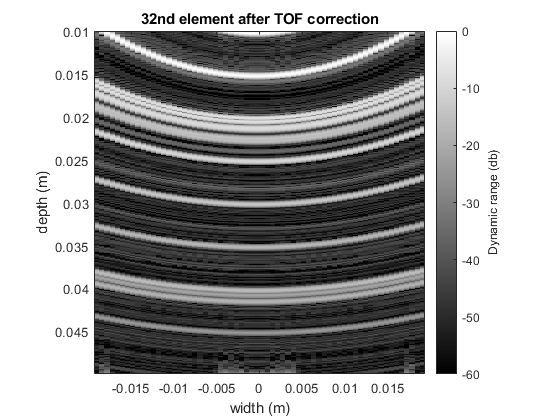

env32 = hilbert(delayed_data([1:end],[1:end],32)); % perform Hilbert
env_abs32 = abs(env32/max(max(env32))); % compute absolute value   
env_db32 = mag2db(env_abs32); % convert to dB

%Visualization
figure();
imagesc(x_axis,z_axis,env_db32(1:end,1:end));
caxis([-60, 0]);
title('32nd element after TOF correction');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

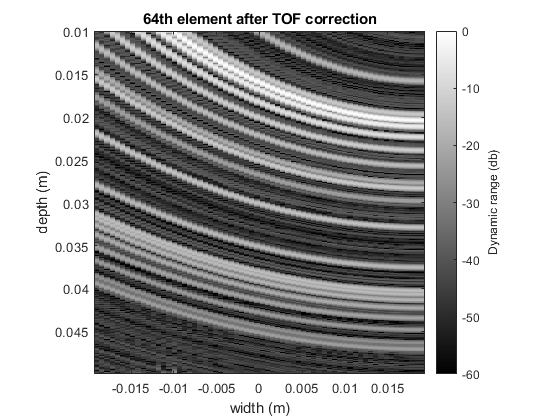

env64 = hilbert(delayed_data([1:end],[1:end],64)); % perform Hilbert
env_abs64 = abs(env64/max(max(env64))); % compute absolute value
env_db64 = mag2db(env_abs64); % convert to dB

%Visualization
figure();
imagesc(x_axis,z_axis,env_db64(1:end,1:end));
caxis([-60, 0]);
title('64th element after TOF correction');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**ANSWER:**

**The images show how the signal waves propagate with respect to their travel time. The 1st and 64th element were located on the edges. Thus, their signals seem to propagate from the corners. Since the 32nd element is located in the middle, its signal propagates from the middle.**

### Assignment 5 - Maximum Likelihood estimation

**QUESTION 5a** 

To reconstruct the underlying tissue scattering $x$, we need to invert the model presented in (2). 

Under the assumption of white gaussian noise $\mathit{\mathbf{n}}~N\left(0,\sigma_n^2 I\right)$, and ${\mathit{\mathbf{a}}}_{\theta \;} =1$ (uniform array response), find the Maximum-Likelihood Estimator for $x$.

**ANSWER:**

Likelihood function can be written as: (The probability density function of Gaussian distribution)


$$L\left(y|x\right)=\frac{1}{{\left(2\pi \sigma \right)}^{\frac{N}{2}} }\exp \left(-\frac{1}{2\sigma^2 }\sum_{n=0}^{N-1} {\left(y_n -x\right)}^2 \right)$$


Take logarithm of the both sides in order to convert likelihood function tractable.


$$\begin{array}{l}
\ln \left(L\left(y|x\right)\right)=\ln \left(\frac{1}{{\left(2\pi \sigma \right)}^{\frac{N}{2}} }\exp \left(-\frac{1}{2\sigma }\sum_{n=0}^{N-1} {\left(y_n -x\right)}^2 \right)\right)\\
\ln \left(L\left(y|x\right)\right)=-\frac{N}{2}\ln \left(2\pi \sigma \right)-\frac{1}{2\sigma }\sum_{n=0}^{N-1} {\left(y_n -x\right)}^2 
\end{array}$$


Take derrivate of the log-likelihood function respect to obersvations (tissue scattering) in order to find maximum likelihood estimation which is the log-likelihood of scattering intenstiy at maxima,


$$\frac{\partial }{\partial x}\ln \left(L\left(y|x\right)\right)=\left(\frac{2}{2\sigma^2 }\sum_{n=0}^{N-1} \left(y_n -x\right)\right)$$


Therefore, derrivative equal to the zero:


$$\begin{array}{l}
\frac{\partial }{\partial x}\ln \left(L\left(y|x\right)\right)=0\;\to \frac{1}{\sigma^2 }\left(\sum_{n=0}^{N-1} \left(y_n -x_{\textrm{ML}} \right)\right)=0\\
\\
x_{\textrm{ML}} =\frac{1}{N}\sum_{n=0}^{N-1} y_n \\
x_{\textrm{ML}} =\frac{1}{N}\cdot {\left\lbrack \begin{array}{ccccccc}
y_0  & y_1  & \cdots  & \cdots  & \cdots  & \cdots  & y_{N-1} 
\end{array}\right\rbrack }_{N\times 1} \cdot {\left\lbrack \begin{array}{c}
1\\
1\\
1\\
\vdots \\
\vdots \\
1
\end{array}\right\rbrack }_{1\times N} 
\end{array}$$


**QUESTION 5b**

Implement the ML estimator found in the previous question, and plot the reconstructed image using the envelope detection and log-compression as in question **4b **and **4c**.

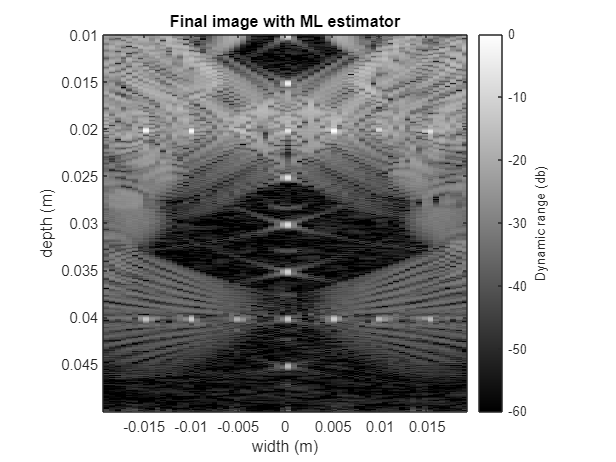

% ML estimator and visualization (~5 lines of code)
ML = 1/(sz(2)); % Number of observations
sum5b = zeros(1301,64,1); % Ml estimator matrix
for i=1:sz(2)
    sum5b=sum5b+(delayed_data(1:end,1:end,i)*ML); % apply ML estimator on data
end

env2 = hilbert(sum5b([1:end],[1:end])); % perform Hilbert
env_abs2 = abs(env2/max(max(env2))); % compute absolute value
env_db2 = mag2db(env_abs2); % convert to dB

% Visualization (~2 lines of code)
figure();
imagesc(x_axis,z_axis,env_db2);
caxis([-60, 0]);
title('Final image with ML estimator');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**QUESTION 5c**

Let us now include the array response of the transducer. Assume that ${\mathit{\mathbf{a}}}_{\theta \;}$ follows a Hanning window, and calculate the new ML estimate of x. Plot the reconstructed image, do you see any differences compared to the previous approach? Can you say something about the resolution and contrast in the image?

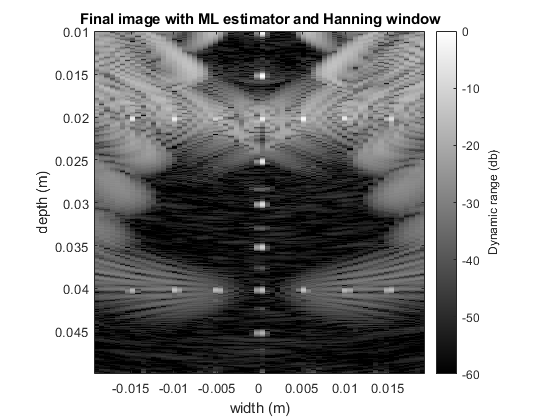

% ML estimator and visualization (~5 lines of code)
sum1 = zeros(1301,64,1);
w = hann(64); % Hanning window
for i=1:sz(2)
    sum1=sum1+(delayed_data(1:end,1:end,i)*ML)*w(i); % apply ML estimator and Hanning window on data
end

env3 = hilbert(sum1([1:end],[1:end])); % perform Hilbert
env_abs3 = abs(env3/max(max(env3))); % compute absolute value
env_db3 = mag2db(env_abs3); % convert to dB

% Visualization (~2 lines of code)
figure();
imagesc(x_axis,z_axis,env_db3);
caxis([-60, 0]);
title('Final image with ML estimator and Hanning window');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**ANSWER:**

**In comparison to the previous approach (Rectangular window), the new image has higher contrast and poor resolution. This can be explained by the Hanning window having lower main lobe width and side lobe height in their normalized frequency spectra. Correspondingly, in the rectangular window, the peaks are better distinguished, while the Hann window provides less leakage. Thus, different window selection leads to the Time-Bandwidth trade-off between resolution and leakage in the finite-length window.**

                                               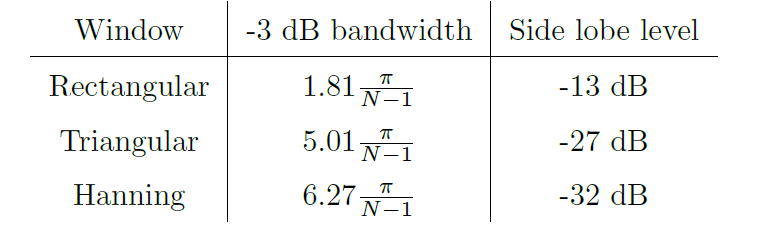

**The trade-off between resolution and leakage is based on the bias of the window signal which is the convolution between the true power spectrum and window.**

### Assignment 6 - Colored Noise

The white noise assumption used in the previous assignment is a very rough approximation of a realistic measurement. To improve on this, we are going to assume a colored noise profile $\mathit{\mathbf{n}}~N\left(0,C_n \right)$, where $C_n$ is the noise covariance matrix. 

**QUESTION 6a**

Derive the ML estimate for a colored noise profile.

**ANSWER:**

We essentially minimizing:


$$\begin{array}{l}
-\frac{1}{2}{\left(\mathrm{y}-a_{\theta } \mathrm{x}\right)}^T C_x^{-1} \left(\mathrm{y}-a_{\theta } \mathrm{x}\right)\\
=-\frac{1}{2}\left({\mathrm{y}}^T C_x^{-1} \mathrm{y}-{\mathrm{y}}^T C_x^{-1} a_{\theta } \mathrm{x}-{a_{\theta } }^T {\mathrm{x}}^T C_x^{-1} \mathrm{y}+{\mathrm{x}}^T {a_{\theta } }^T C_x^{-1} a_{\theta } \mathrm{x}\right)\\
\frac{\partial }{\partial x}\left(\ln \left(L\left(\mathrm{y}|\mathrm{x}\right)\right)\right)=-\frac{1}{2}\left(-{\mathrm{y}}^T C_x^{-1} a_{\theta } -{a_{\theta } }^T C_x^{-1} \mathrm{y}+2{a_{\theta } }^T C_x^{-1} a_{\theta } \mathrm{x}\right)\\
-\frac{1}{2}\left(2{a_{\theta } }^T C_x^{-1} \mathrm{y}+2{a_{\theta } }^T C_x^{-1} a_{\theta } \mathrm{x}\right)=0\\
{a_{\theta } }^T C_x^{-1} \mathrm{y}={a_{\theta } }^T C_x^{-1} a_{\theta } \mathrm{x}\\
{\left({a_{\theta } }^T C_x^{-1} \mathrm{y}\right)\left({a_{\theta } }^T C_x^{-1} a_{\theta } \right)}^{-1} \\
a_{\theta } \;\textrm{is}\;\textrm{assumed}\;\textrm{as}\;1,\\
{\mathrm{x}}_{\textrm{ML}} =\left({1^T C}_x^{-1} \mathrm{y}\right){\left({1^T C}_x^{-1} 1\right)}^{-1} 
\end{array}$$


**QUESTION 6b**

The noise covariance matrix is generally not known, and varies across the medium and across acquisitions. A solution to this is estimating the covariance from the received data. Because the echo signals are (approximately) zero-mean we can estimate the noise covariance matrix by calculating the spatial covariance matrix $C_n \approx C_y =E\left\lbrack {\textrm{yy}}^{t\;} \right\rbrack$.

However, a problem that can occur with this method is that the inversion of the covariance matrix can be numerically unstable. To solve this we can apply diagonal loading, in which we add a (small) constant to the diagonal of the covariance matrix given by $\frac{D}{M}\textrm{trace}\left(C\right)$, where $M$ denotes the number of array elements, and $D$ is a diagonal loading factor. 

Estimate the noise covariance $\hat{\mathbf{C}} =E\left\lbrack {\textrm{yy}}^{t\;} \right\rbrack$ for each pixel (x,z) in the image, using a diagonal loading factor $D=5$.

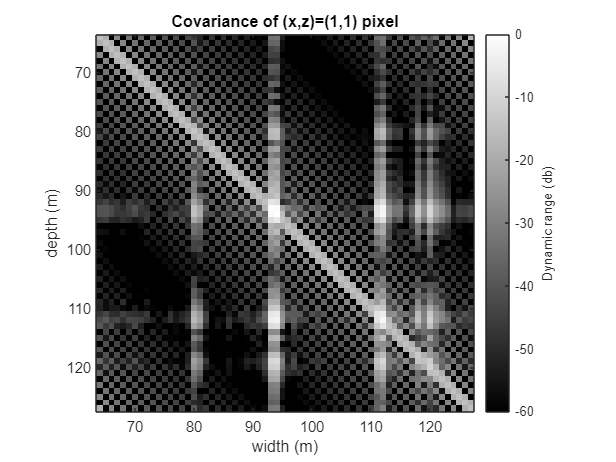

% Estimate the signal covariance per pixel 
newArray = zeros(1301,64,64,64); % array for covariance of each pixel
for i=1:1301
    for j=1:64
        arrayPixel = (delayed_data(i,j,1:end));
        arrayPixel = reshape(arrayPixel,[64,1]);
        y = arrayPixel*transpose(arrayPixel); % compute covariance
        loadfac = (5/64)*trace(y)*eye(64,64); % implement load factor
        newArray(i,j,1:end,1:end) = y+ loadfac; % save covariance matrix to array
    end
end

env6 = hilbert(newArray(1,1,[1:end],[1:end])); % perform Hilbert
env_abs6 = abs(env6/max(max(env6))); % compute absolute value
env_db6 = mag2db(env_abs6); % convert to dB
env_db6 = reshape(env_db6,[64,64]);

%Visualization
figure();
imagesc(64,64,env_db6);
caxis([-60, 0]);
title('Covariance of (x,z)=(1,1) pixel');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**QUESTION 6c**

Implement the ML estimator derived in question **6a**, and use the noise covariance derived in question **6b**.

Plot the resulting image. What differences do you observe compared to the images in question **5**.

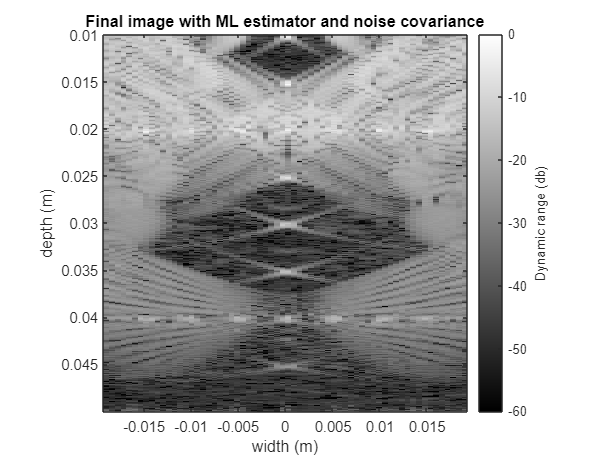

% Implement the ML estimator with colored noise (~5-10 lines of code)
MLE = zeros(1301,64); % MLE array
C = zeros(64,64); % Covariance
for i=1:1301
    for j=1:64
        % Calculate covariance for each pixel
        arrayPixel_6c = (delayed_data(i,j,1:end));
        arrayPixel_6c = reshape(arrayPixel_6c,[64,1]);
        y_6c = arrayPixel_6c*transpose(arrayPixel_6c);
        loadfac_5 = (5/64)*trace(y_6c)*eye(64,64);
        C = y_6c+loadfac_5;
        % Calculate MLE for the final image
        tmp1 = (ones(64,1)\C)*arrayPixel_6c;
        tmp2 = 1/sum(sum(C));
        MLE(i,j) = tmp1*tmp2;
    end
end
% Envelope detection
envMLE = hilbert(MLE([1:end],[1:end]));
env_abs = abs(envMLE/max(max(envMLE)));
env_db = mag2db(env_abs);
% Vizualization
imagesc(x_axis,z_axis,env_db);
caxis([-60, 0]);
title('Final image with ML estimator and noise covariance');
xlabel('width (m)');
ylabel('depth (m)');
h = colorbar;
ylabel(h, 'Dynamic range (db)');
colormap gray; axis image;

**QUESTION 6d**

We have now used a relatively small diagonal loading factor. What would happen if we select a value that is (too) high? Can you comment on the assumed noise model?

**ANSWER:**

**Single Pixel Covariance and Output of Maximum Likelihood Estimator:**

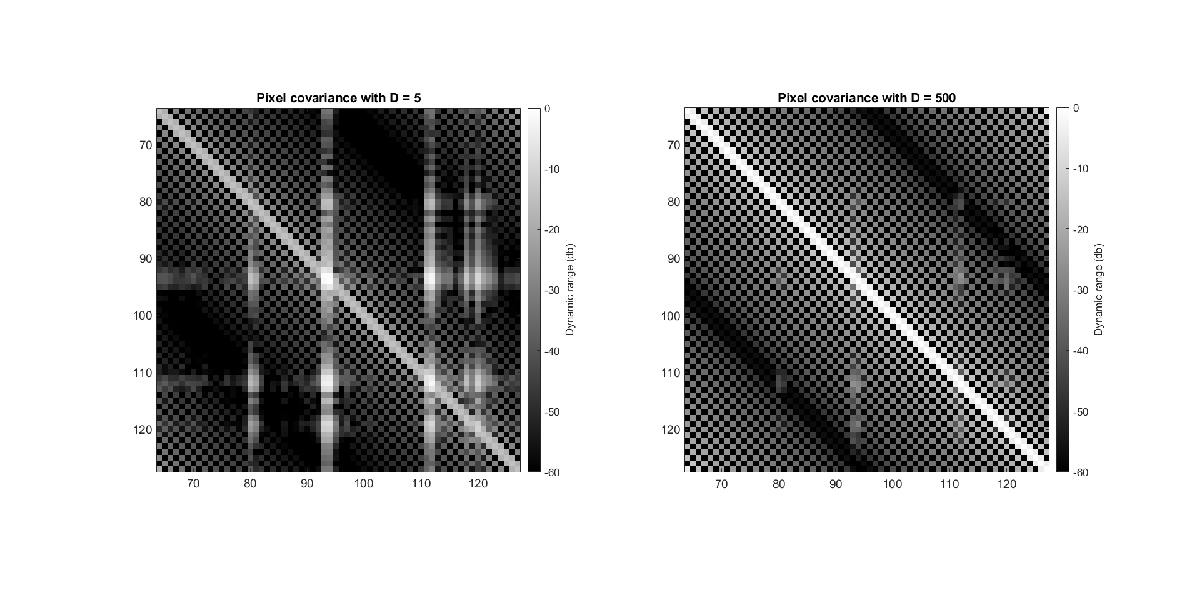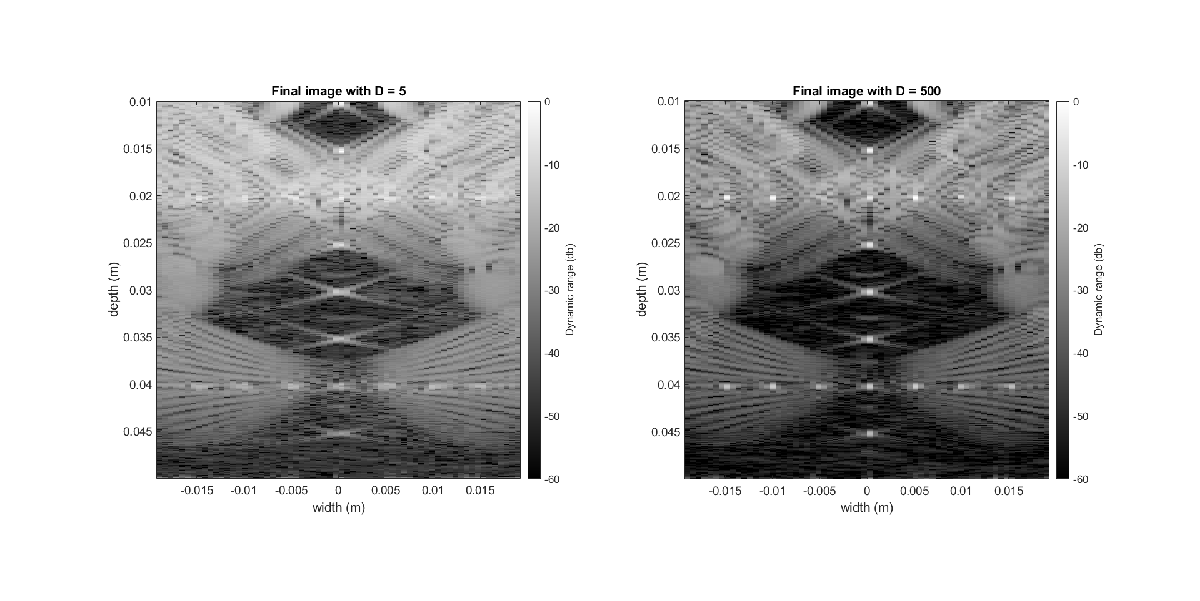

As expected, the covariance matrix becomes diagonal once the loading factor increases from 5 to 500. 

Diagonal covariance indicates that they are uncorrelated / or significantly less correlated (as we can still see values that are not on the diagonal).

There are two main differences between the results of the ML estimator before and after increasing the loading factor. 

First, value contrast increases as the diagonal factor rises. The second case involves suppressing lower signal values to make them less dominant and visible.